# Project - Guitar Tab Reader

ELEX 7815 - Digital Image Processing

Max Horie, A01010912

addpath('C:\Users\maxho\Documents\School\3. Fall 2020\ELEX 7815 - Digital Image Processing\Project\')

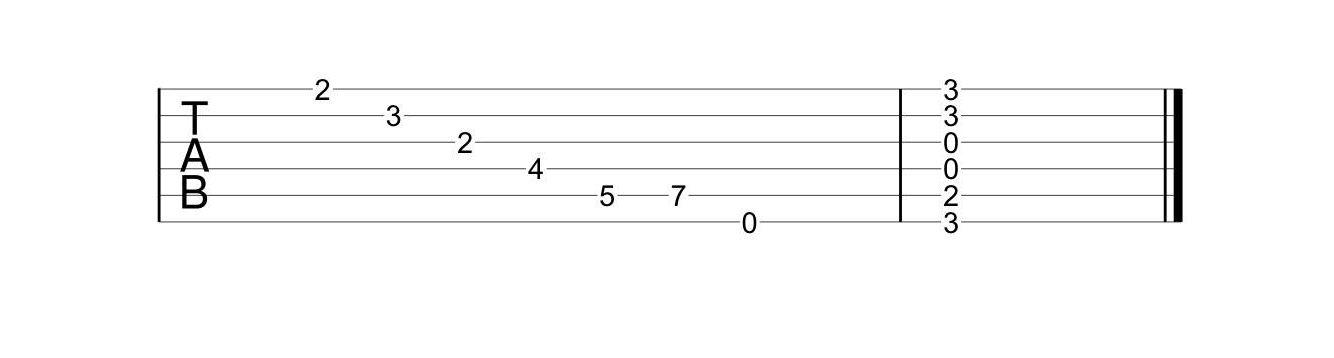

I = imread("Easy.jpg");
imshow(I)

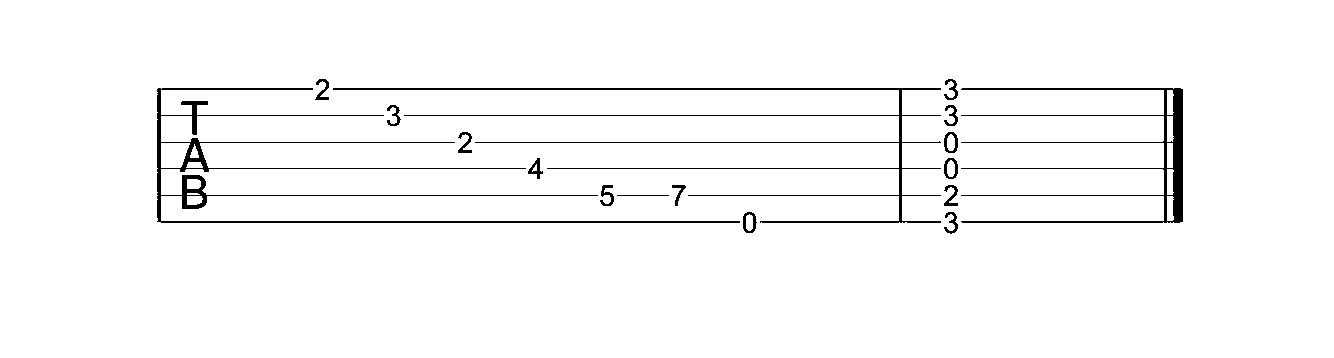


%make black and white, invert, remove border
[I, I_inv] = init(I); 
imshow(I)

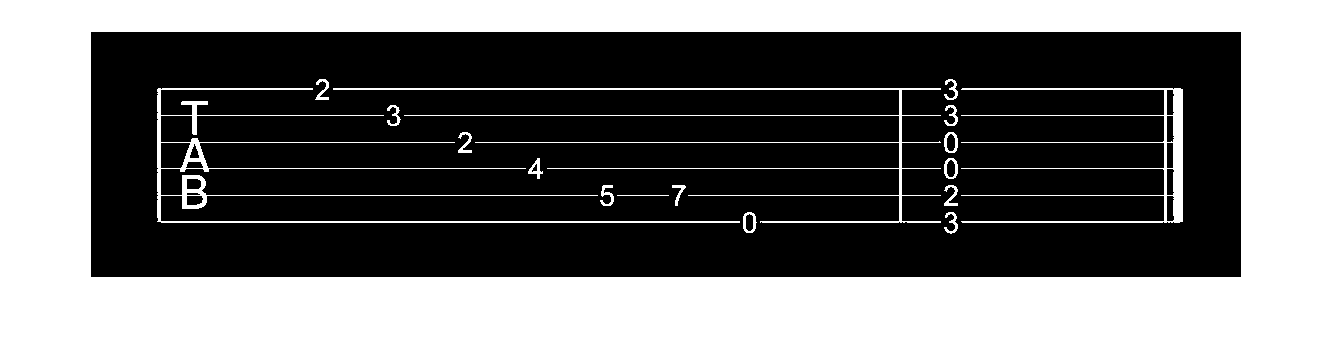

imshow(I_inv)

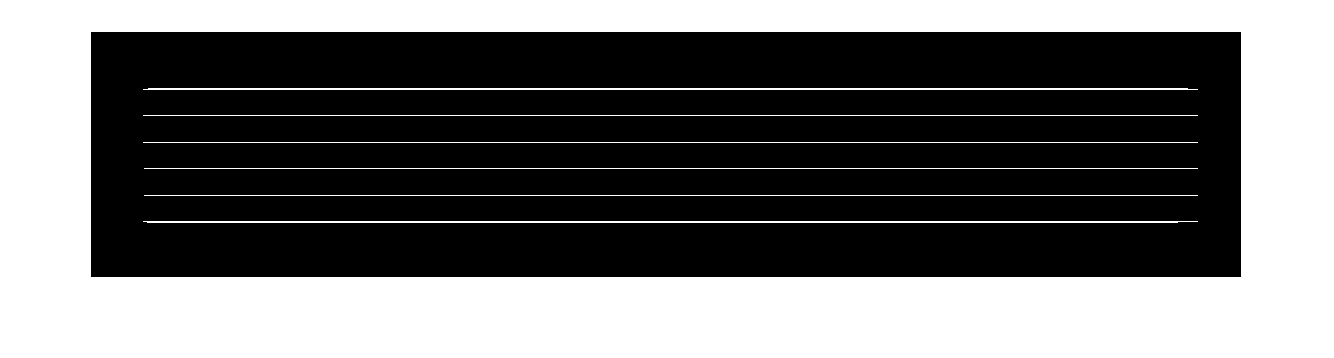


%find horizontal measure lines
[I_inv_lines,I_inv_lines_2,row_vec] = find_horz_lines(I_inv);
imshow(I_inv_lines) 

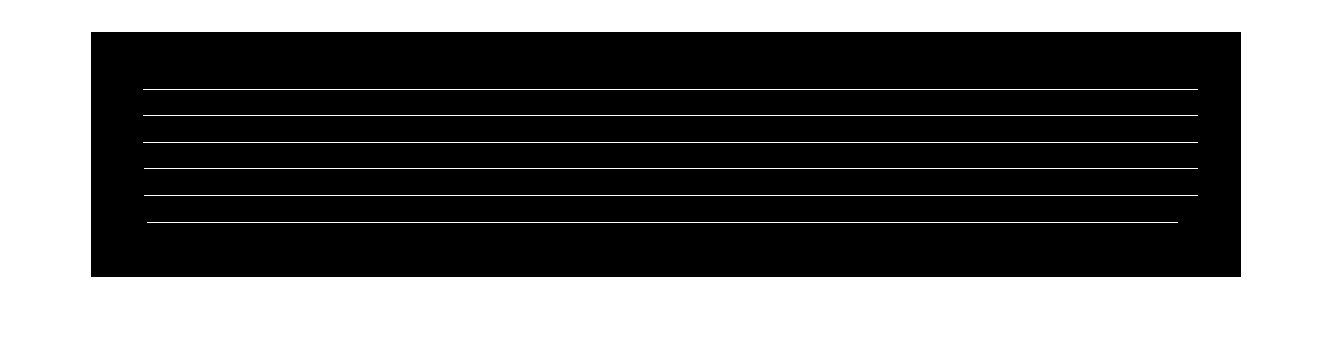

imshow(I_inv_lines_2)

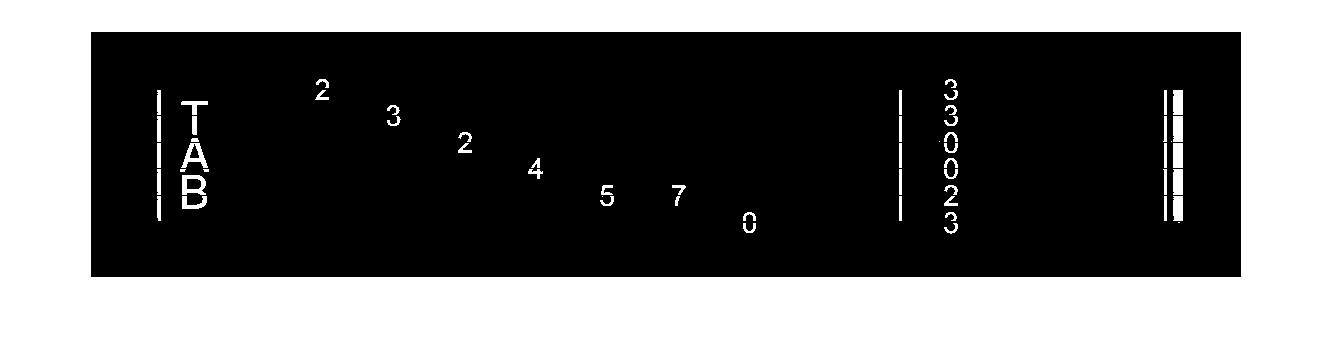

imshow(I_inv-I_inv_lines) 


%find vertical measure lines
[I_inv_linesv,I_inv_linesv_2,col_vec] = find_vert_lines(I_inv,row_vec);
col_vec

col_vec =           70
         811
        1076
        1092


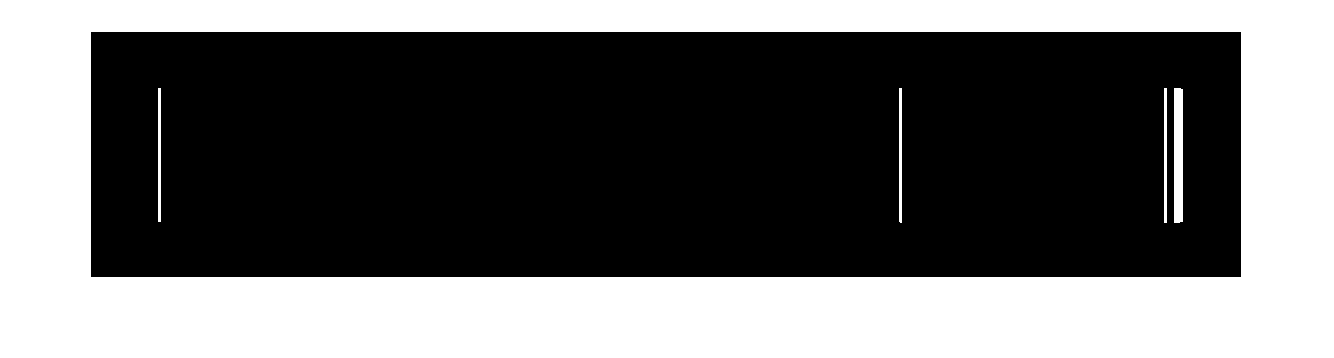

imshow(I_inv_linesv)

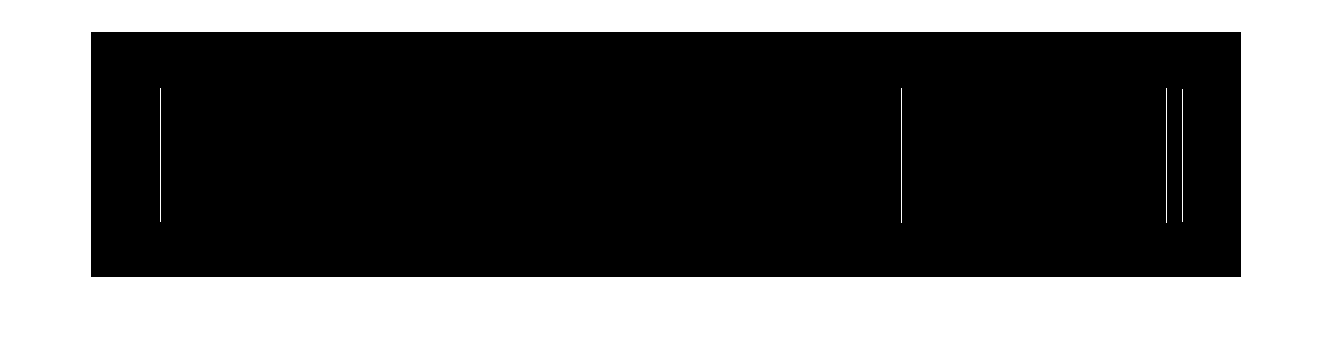

imshow(I_inv_linesv_2)

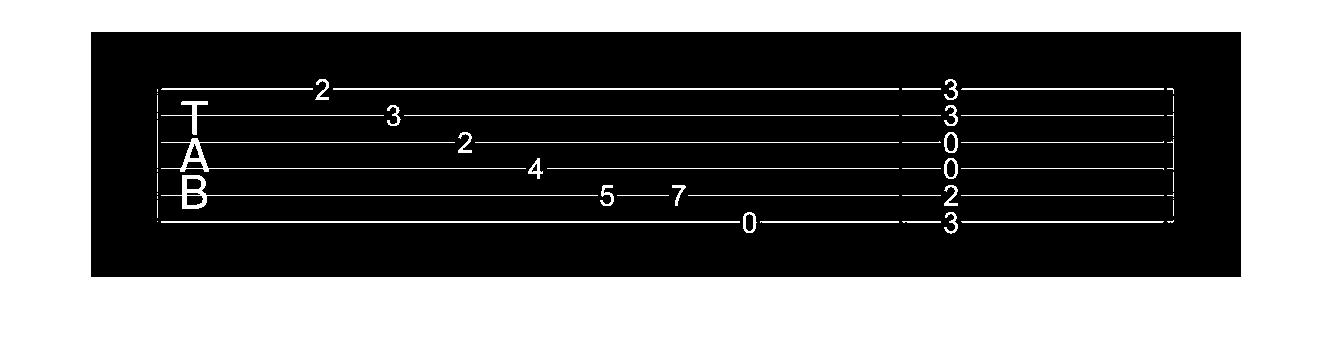

imshow(I_inv-I_inv_linesv)

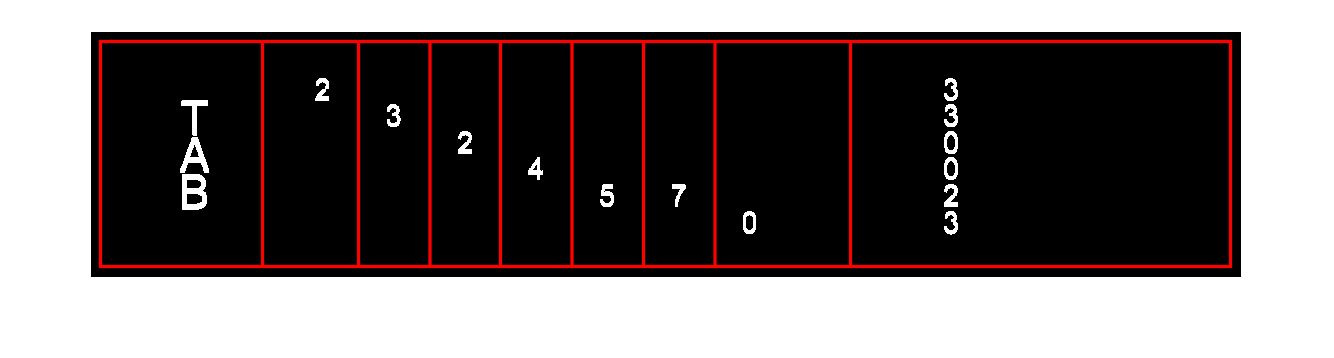


%remove horz & vert lines from image and anything outside of it (chars
%remain), form bounding boxes (note_col) and detect chars using ocr 

%ocr function returns chars, including word, character, confidence level,
%and location
[I_no_hv,chars,note_col] = detect_char(I_inv,I_inv_lines,I_inv_linesv,row_vec,col_vec);


fs = 44.1e3;          %sampling frequency
bpm = 60;             %beats per minute

%determine fret number from chars and string from location and row vector
%play the notes using the Karplus-Strong algorithm for finding frequencies
%display the fret, string, note, and frequency
play_tab(fs,bpm,chars,row_vec,note_col);


Note/Chord 1:
	A is not a number
	B is not a number
	  is not a number
	T is not a number
Note/Chord 2:
	Fret 2, e string. Note = D, f = 370.0 Hz
Note/Chord 3:
	Fret 3, B string. Note = G#, f = 293.7 Hz
Note/Chord 4:
	Fret 2, G string. Note = F, f = 220.0 Hz
Note/Chord 5:
	Fret 4, D string. Note = A#, f = 185.0 Hz
Note/Chord 6:
	Fret 5, A string. Note = E, f = 146.8 Hz
Note/Chord 7:
	Fret 7, A string. Note = D, f = 164.8 Hz
Note/Chord 8:
	Open E string. Note = E, f = 82.4 Hz
Note/Chord 9:
	Fret 3, e string. Note = C#, f = 392.0 Hz
	Fret 3, B string. Note = G#, f = 293.7 Hz
	Open G string. Note = G, f = 196.0 Hz
	Open D string. Note = D, f = 146.8 Hz
	Fret 2, A string. Note = G, f = 123.5 Hz
	Fret 3, E string. Note = C#, f = 98.0 Hz

**Functions**

function [I, I_inv] = init(I)
    if size(I,3) == 3 %if rgb image, convert to gray
        I = rgb2gray(I);
    end
    
    thresh = 0.7; %set high threshold to convert artifacts to white
    I = im2bw(I,thresh);
    
    I_inv = imcomplement(I); %invert to use dilate + erode functions
    
    %remove any border (size 1 or 2)
    for i = 1:size(I_inv,1)
        for j = 1:size(I_inv,2)
            if (i < 3 || i > (size(I_inv,1) - 2)) || (j < 3 || j > (size(I_inv,2) - 2)) %if border of one or two pixels, make black
                I_inv(i,j) = 0;
            end
        end
    end
end

function [I_inv_lines,I_inv_lines_2,a] = find_horz_lines(I_inv)
    
    %erode, dilate horizontally to expose horz lines
    I_inv_lines = imerode(I_inv,ones(1,round(size(I_inv,2)/40)));
    I_inv_lines = imdilate(I_inv_lines,ones(1,round(size(I_inv_lines,2)/20)));
    
    %find all rows with white in them
    [a b] = find(I_inv_lines==1);
    a = unique(a);
    c = zeros(size(a));
    
    %if lines are shorter than half the page, remove
    for j = 1:size(a)
        if sum(I_inv_lines(a(j),:)) < size(I_inv_lines,2)/2
            I_inv_lines(a(j),:) = 0;
            c(j) = a(j);
        end
    end
    
    I_inv_lines_2 = I_inv_lines;
    
    %if lines are doubled, remove one
    for i = 1:size(a)-1
        if a(i+1)-a(i) == 1
            c(i) = a(i);
            I_inv_lines_2(a(i),:) = 0;
        end
    end
    
    %remove rows vector that are too short or doubled 
    a = a - c;
    a = nonzeros(a);

end

function [I_inv_linesv,I_inv_linesv_2,b] = find_vert_lines(I_inv,a)
    %erode, dilate vertically to expose vert lines
    I_inv_linesv = imerode(I_inv,ones(round(size(I_inv,2)/20),1));
    I_inv_linesv = imdilate(I_inv_linesv,ones(round(size(I_inv,2)/20),1));
    
    %find all columns with white
    [x b] = find(I_inv_linesv==1);
    b = unique(b);
    c = zeros(size(b));
    
    %if lines are shorter than length of 6 rows, remove
    for j = 1:size(b)
        if sum(I_inv_linesv(:,b(j))) < (a(6)-a(1))+(a(1)-a(2))
            I_inv_linesv(:,b(j)) = 0;
            c(j) = b(j);
        end
    end
    
    I_inv_linesv_2 = I_inv_linesv;
    
    %if lines are doubled, remove one
    for i = 1:(size(b)-1)
        if b(i+1)-b(i) == 1
            c(i) = b(i);
            I_inv_linesv_2(:,b(i)) = 0;
        end
    end
    
    %remove columns from column vector that are too short or doubled 
    b = b - c;
    b = nonzeros(b);

end

function[I_no_hv,txt,out] = detect_char(I_inv,I_inv_lines,I_inv_linesv,a,b)

    %if items are outside bounds given by rows/columns (with tolerance) found, remove
    for i = 1:size(I_inv,1)
        for j = 1:size(I_inv,2)
           if ((i < a(1)-(a(2)-a(1))/2) || (i > a(end)+(a(2)-a(1))/2)) || ((j <= b(1)) || (j >= b(end)-10))
               I_inv(i,j) = 0;           
           end
        end
    end
    
    I_no_hv = I_inv - I_inv_lines - I_inv_linesv;               %create image with no pure horz/vert lines
    small = bwareafilt(imbinarize(I_no_hv),[0 5]);              %locate tiny white areas
    I_no_hv = I_no_hv - small;                                  %remove tiny white areas from image
    I_no_hv = imdilate(I_no_hv,ones(round((a(2)-a(1))/8),1));   %dilate image based on distance between rows
    imshow(I_no_hv)
    
    toggle = 0; 
    out = [];
    for i = 1:size(I_no_hv,2)                         %loop through columns
        if sum(I_no_hv(:,i)) > 0 && toggle == 0       %if transition from black to white
            toggle = 1;                               %toggle
            out(end+1,1) = i;                         %add transition location
        elseif sum(I_no_hv(:,i)) == 0 && toggle == 1  %if transition from white to black
            toggle = 0;                               %toggle
            out(end,2) = i;                           %add transition location
        end
    end
    
    for i = 1:size(out,1) %loop through transition vector
        if i == 1 %first blob location
            location_rect = [10 10 ((out(i+1,1)+out(i,2))/2-10) size(I_no_hv,1)-20]; %create box around blob
        elseif i == size(out,1) %last blob location
            location_rect = [(out(i,1)+out(i-1,2))/2 10 (size(I_no_hv,2)-(out(i,1)+out(i-1,2))/2-10) size(I_no_hv,1)-20]; %create box around blob
        else
            location_rect = [(out(i,1)+out(i-1,2))/2 10 ((out(i,2)+out(i+1,1))/2-(out(i,1)+out(i-1,2))/2) size(I_no_hv,1)-20]; %create box around blob
        end
        rectangle('Position',location_rect,'EdgeColor',[1 0 0],'LineWidth',2)                        %overlay rect on image
        txt(i) = ocr(~I_no_hv,location_rect,'CharacterSet','0123456789TAB','TextLayout','Block');    %optical character recognition of char in boxes
    end
end

function play_tab(fs,bpm,txt,a,out)
    freq = [];            %sets current chord frequencies
    a_freq = 110;         %frequency of A string (open) in Hz
    bps = bpm/60;         %beats per second
    note_length = 1/bps;  %note duration 
    
    note_int = 1:12; %temp octave vector to allow for circular shifting
    notes = ["A", "A#", "B", "C", "C#", "D", "D#", "E", "F", "F#", "G", "G#"]; %notes in scale
    
    %find each note's information
    for j = 1:size(out)                                             %loop through transition vector
        fprintf('\nNote/Chord %d:',j)
        for k = 1:size(txt(j).Words)                                %loop through each char in word
            fret = char(txt(j).Words(k));                           %fret number
            if isstrprop(fret,'digit')                              %check if char is numeric                                
                x1 = txt(j).CharacterBoundingBoxes(2*k-1,2);        %first column bound of char
                x2 = x1 + txt(j).CharacterBoundingBoxes(2*k-1,4);   %second column bound of char
                [val,idx] = min(abs(a-(x2+x1)/2));                  %find closest row to char
                
                switch idx %Gives string offsets with A = 110Hz, finds note from fret + string
                    case 1
                        string = 'e';
                        shift = circshift(note_int,double(fret));
                        note = notes(shift(8));
                        offset = 19;
                    case 2
                        string = 'B';
                        shift = circshift(note_int,double(fret));
                        note = notes(shift(3));
                        offset = 14;
                    case 3
                        string = 'G';
                        shift_ = circshift(note_int,double(fret));
                        note = notes(shift_(11));
                        offset = 10;
                    case 4
                        string = 'D';
                        shift = circshift(note_int,double(fret));
                        note = notes(shift(6));
                        offset = 5;
                    case 5
                        string = 'A';
                        shift = circshift(note_int,double(fret));
                        note = notes(shift(1));
                        offset = 0;
                    case 6
                        string = 'E';
                        shift = circshift(note_int,double(fret));
                        note = notes(shift(8));
                        offset = -5;
                end
               
                freq(k) = a_freq*2^((str2double(fret)+offset)/12); %determine frequency of fret + string combo using equation
                
                if char(txt(j).Words(k)) == '0' %if char is 0, print open (guitar speak for no fret pressed)
                    fprintf('\n\tOpen %c string. Note = %s, f = %0.1f Hz',string,note,freq(k));    
                else
                    fprintf('\n\tFret %c, %c string. Note = %s, f = %0.1f Hz',fret,string,note,freq(k)) %print fret, string 
                end
            else
                fprintf('\n\t%c is not a number',fret) %if char is not number
            end
        end    
       
        value = [0:1/fs:note_length]; %choose time values to play sinusoid
        if size(freq,1) > 0         %if no numeric notes, skip
             for l = 1:size(freq) %loop through each frequency in chord
                 sound(sin(2*pi*freq(l)*value),fs) %play sound (sin(2pift)) sampled at fs
             end
            pause(note_length)
        end
    end
end